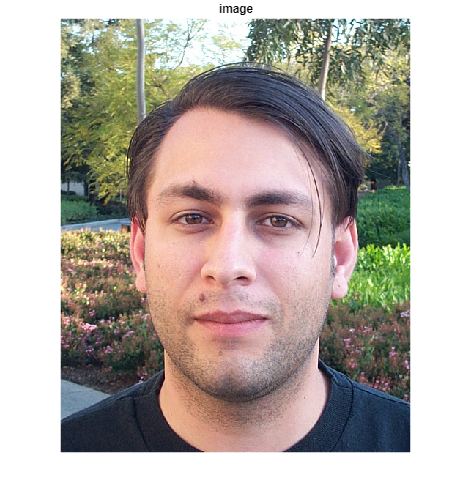

clear all
image = imread("./Faces/db0_" + 2 + ".jpg");
%image = imread("./Faces/db2/bl_" + 6 + ".jpg");

%image = randomTransform(image, [0, 0],[5, 5], [0.9, 1.1]);
imshow(image); title('image')

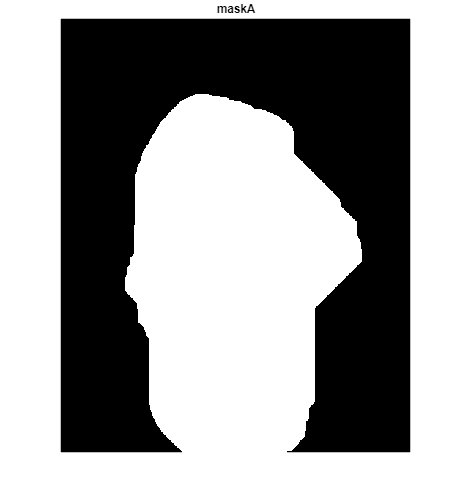

Index in position 2 is invalid. Array indices must be positive integers or logical values.

Error in windowFromMouthMap (line 42)
    mask(round((ce(2)-1.0*n/3)):round((ce(2)-0.2*n/3)), round(ce(1)-m/4):round(ce(1)+m/4),1) = 1;

Error in findEyes (line 36)
    map = map .* windowFromMouthMap(faceCorrected);


[eye1,eye2] = findEyes(image);

im = showEyes(image,eye1, eye2);
imshow(im);title('X')

%normalized_img = faceNormalization(image,eye1,eye2);
%imshow(normalized_img)
%id = getFaceId(normalized_img, 1000);